MECE6397: Learning-Based Control 

# Homework 5: Iterative Learning Control (ILC) of the DC-servo

Instructor: Marzia Cescon

## 1. Learning from repetitions

Iterative learning control (ILC) is a method used to compensate for errors resulting from the **execution of the same task repeatedly **[1]. When a system executes the same task multiple times it is indeed possible to use knowledge of the control performance from previous executions to try to reduce the error next time the task is repeated. Take for instance a basketball player shooting a free throw from a fixed position: by practicing the shot repeatedly, the player can improve the ability to score. During each attempt, the player observes the trajectory of the ball and based on the performance achieved plans a modification to the shooting motion for the next attempt. As the player keeps practicing, the motion that leads to a score is learned, so that the shooting accuracy is iteratively improved. This iteratively learned motion profile is an open-loop control strategy at the essence of ILC. For systems that perform the same task repeatedly under the same operating conditions, a nonlearning controller yields the same tracking error on each pass. By incorporating error information from previous iterations into the control architecture, the objective of the ILC is to modify the control input signal to progressively reduce the tracking error and achieve the desired performance. Errors in the reference following can have many causes: unmodelled dynamics, poorly tuned control parameters, different kinds of disturbances, measurement noise, friction etc. If the system response is highly repeatable, in the sense that a certain reference signal sequence will generate roughly the same response whenever it is repeated, then ILC can be applied to decrease the control error. However, if stochastic disturbances dominate or if the dynamics vary from one run to another, other methods than ILC should be considered.

### 1.1 About the time scales

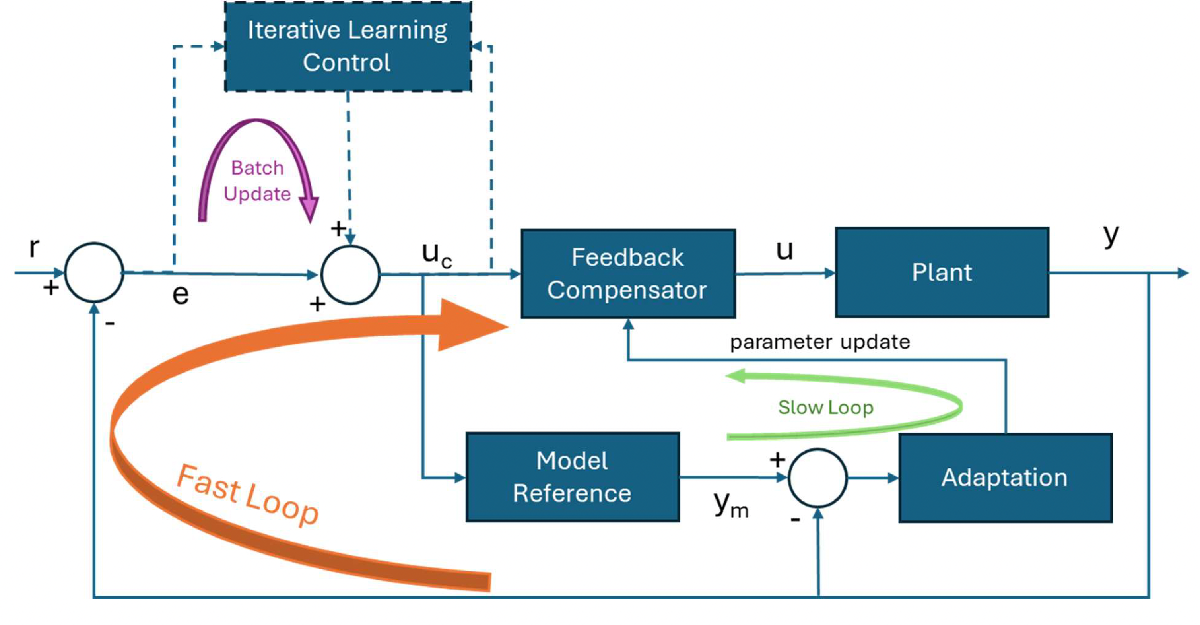

*Figure 1: Block diagram illustrating controllers timescales.*

To put ILC into perspective, Figure 1 gives a schematic representation of a feedback loop with controllers operating at different time scales. Ordinary feedback occurs on the fastest timescale, where a relatively high-bandwidth compensator is applied to the error signal between the plant output and the reference, to achieve reference following and disturbance rejection. Adaptive parameter updates also occur in real-time but at a slower rate than ordinary feedback. In model reference adaptive control, for example, the error between the plant output and the model reference is used with an adaptation law that gradually updates the parameters of the feedback compensator to achieve better model tracking. Iterative learning occurs offline in between iterations of the same task. It is based on adjusting the reference signal (in serial ILC) or the input signal (in parallel ILC) to correct for recurring residual errors that were not eliminated by the other two methods.

## 2. ILC formulation

The ILC method is intuitive and simple. In short, the method consists of the following steps.

- At iteration $k$, apply the desired reference signal sequence $\left\lbrace y_d \left(t\right)\right\rbrace$, where $t\;$denotes the discrete-time index, to the system and record the tracking error sequence $\left\lbrace e_k \left(t\right)\right\rbrace =\left\lbrace y_d \left(t\right)\right\rbrace -\left\lbrace y_k \left(t\right)\right\rbrace$.

- Based on the error sequence, modify the control signal$\left\lbrace u_k \left(t\right)\right\rbrace$ to improve the response for the next iteration $k+1$.

A common update law for ILC used to modify the control signal is: 


$$u_{k+1\;} \left(t\right)=Q\left(q\right)\left\lbrack u_k \left(t\right)+L\left(q\right)e_k \left(t\right)\right\rbrack \;$$


with $Q\left(\cdot \right)$ and $L\left(\cdot \right)$linear filters. These two steps are repeated until the deviation of the controlled variable from the reference is acceptable. Note that the ILC-based correction of the control signal $\left\lbrace u_k \left(t\right)\right\rbrace$ is pre-determined and applied in open-loop during one run, but is updated from feedback information between the runs, in batch-wise fashion.

### 2.1 Error analysis and convergence

At iteration $k$, the following equations describe the ILC problem:


$$y_k(t)= G(q)u_k(t) \\ 
e_k(t) = y_d(t) - y_k(t)\\
u_{k+1} = Q(q)[u_k(t)+L(q)e_k(t)]$$


Converge of the algorithm can be studied by analyzing the error dynamics:

$e_{k+1} = y_d(t) - y_{k+1}(t) =  y_d(t) - G(q) u_{k+1}(t) = y_d(t) - G(q)[Q(q)(u_{k}(t)+L(q)e_k(t))] $ which, after some calculations, can be expressed by the following recursive equation: 


$$e_{k+1}(t) = (1-Q(q))y_d(t)+Q(q)(1-G(q)L(q))e_k(t)$$


Converge will be achieved if the following inequality holds true:


$$\mid 1-G(i\omega) L(i\omega)\mid < \mid Q^{-1}(i\omega)\mid$$


where $\omega \in [-\pi,\pi]$. The problem of ILC design is to choose the filters $Q\left(\cdot \right)$ and $L\left(\cdot \right)$ so that the stability constraint is fulfilled. For more details on ILC methods, an in-depth exposition can be found in [2]. 

In this homework exercise we will examine the design of ILC for for angular position control of a simple DC-servo with a flywheel. We will consider improving the reference following when performing repetitive tasks. 

## 3. The Process

The DC-servo with a flywheel is modelled using Netwon’s second law as a second order process:


$$J\ddot{y} \left(t\right)=-d\dot{y} \left(t\right)+k\;u\left(t\right)+v\left(t\right)$$


where $y\;\left\lbrack \textrm{rad}\right\rbrack$ is the angular position of the servo, $v\;\left\lbrack \textrm{rad}\right\rbrack$ is a disturbance affecting the system, $u\left\lbrack A\right\rbrack$ is the control signal current, $J\;\left\lbrack \textrm{kg}\cdot m^2 \right\rbrack$ is the moment of inertia, $d\;\left\lbrack N\cdot m\cdot s\right\rbrack$ is the coefficient of viscous friction and $k\;\left\lbrack N\cdot m/A\right\rbrack$ is the motor torque constant.

**Task 1.** Write the nominal continuous time transfer function $G\left(s\right)$ between current and angular position. 


$$G(s) = \frac{Y(s)}{U(s)}= \frac{k/J}{s^s+(d/J)s}$$


**Task 2.** A simple system identification experiment allowed to learn the values for $k/J$ and $d/J$ appearing in $G\left(s\right)$. Inspect the Simulink model `pidDCsim.mdl `and retrieve the numerical values of $k/J$ and $d/J$.

open('pidDCsim.mdl')

*Type the numerical values of *$k/J$ and $d/J$. 

## 2. Fixed PID Control

The structure of the regulator used to control the angular position of the servo is fixed to that of a PID-type controller, where the control signal $u\left(t\right)$ is given by the expression:


$$u\left(t\right)=K\left(e\left(t\right)+\frac{1}{T_i }\int e\left(t\right)\textrm{dt}+T_d \frac{d}{\textrm{dt}}e\left(t\right)\right)$$


**Task 3. **Tune a PID controller by trial and error with an acceptable control performance for the servo. Which values of parameters $K,T_i ,T_d$ seem suitable? Test the robustness of your tuning by changing the process parameters during the simulation. Provide plots for the reference tracking and the control error.

clf; figure(1); % 'reset figure' shows only current plot, while 'hold figure' shows previous plots as well.
% The time step of the PID controller
Ts = 0.1;
% This is where you set the values of your PID controller
K = 8;
Ti = 15;
Td = 1.6;
sim('pidDCsim.mdl')
subplot(311)
hold on
plot(tout,output)
plot(tout,ref,'k')
axis([0 50 -0.5 2.5])
grid on
ylabel('Output')
subplot(312)
plot(tout,control)
grid on
axis([0 50 -5 5])
xlabel('Time (sec)')
ylabel('Control')
subplot(313)
plot(tout,control_error)
grid on
axis([0 50 -5 5])
xlabel('Time (sec)')
ylabel('Control error')

In the next section, we will use an ILC scheme to obtain improved tracking performance with the PID in the loop.

## 3. Heuristic approach to ILC design

In this exercise, we will investigate a version of the so-called heuristic approach for the design of the $Q\left(\cdot \right)$ and $L\left(\cdot \right)$ filters [1],[2]. The procedure goes as follows:

- Choose the $Q\left(\cdot \right)$ filter as a low-pass filter with cut-off frequency such that the band-width of the learning algorithm is sufficient.

- Let $L\left(q\right)=\kappa q^{\delta }$. Choose $\kappa$ and $\delta$ such that the stability criterion is fulfilled. 

 Note that as the filtering is made off-line, i.e., between two consecutive runs, when we have access to the whole sequences of data, we may choose $Q\left(\cdot \right)$ and $L\left(\cdot \right)$ to be non-causal filters.

**Task 4.** Given the sequence $\left\lbrack 1:10\right\rbrack$ filter it first with the filter $G_1 \left(z\right)=z^3$ using the function [`noncausalfilter.m`](matlab:open('./noncausalfilter.m'))

% Enter your code.

and then with the filter $G_2 \left(z\right)=\frac{1}{z^3 }$ using the matlab command `filter.`

% Enter your code.

What is the difference between causal and non-causal filtering?

*Enter your text here.*

**Task 5**. Study the Matlab script

p = 30;
alpha = 0.4;
beta = 20;
open('ILC_setup.m')

and also have a look at the ILC-update in

open('run_ILC_iteration')

What are the initial values for the filters $Q_d \left(\ldotp \right)$ and $L_d \left(\ldotp \right)$? How is the ILC algorithm implemented? What commands are used? Why?

*Enter your text here.*

**Task 6.** Open `ILC_pidDCsim.mdl` from the following drop down menu and insert the values $K=0\ldotp 4,T_i =100,T_d =0\ldotp 5$ for the PID controller parameters. Run the ILC iterations by choosing *Run iteration. *Run the section for new iterations. Choose *Reset* to initialize the iterations. How many iterations do you need in order to achieve convergence? Provide plots for the angular position vs. reference, the norm of the tracking error and the ILC correction.

% Filter paramters in ILC_setup.m
p = 30;
alpha = 0.4;
beta = 20;
open('ILC_pidDCsim');

**Task 7.** Modify the filters $Q\left(s\right)=1/\left(s/p+1\right)$ and $L_d \left(z\right)=\alpha z^{\beta }$ in the Matlab script [`ILC_setup.m`](matlab:open('./ILC_setup.m')) for various $p,\;\alpha$ and $\beta$. Provide plots for the angular position vs. reference, the norm of the tracking error and the ILC correction for each case that you considered. Use *Reset* to intialize the simulation each time you investigate new filters.

% Filter paramters in ILC_setup.m
p = 50;
alpha = 0.9;
beta = 13;
run('reset_idx_ILC');

**Task 8.** How does the pole $p$ affect the control signal sequence, any how should it be chosen? How does $\beta$ affect the ILC performance, and what may be a reasonable value? How does $\alpha$ affect the rate of convergence, and what may be a reasonable value?

*Enter your text here.*

**Task 9**. Repeat Task 6 and Task 7 for the controller parameter values $K,T_i ,T_d$ that you calculated in Task 3. What do you observe?

% Filter paramters in ILC_setup.m
p = 50;
alpha = 0.9;
beta = 13;
% Input your PID parameters from Task 3 into ILC_pidDCsim:
open('ILC_pidDCsim');

*Enter your text here.*

Introduce some unmodelled dynamics by modifying the transfer function $G\left(s\right)$ in `ILC_pidDCsim.mdl`. For instance you can think of moving the position of the pole or changing the steady-state gain.

**Task 10.** Repeat Task 6 and Task 7 for the controller parameter values $K,T_i ,T_d$ that you calculated in Task 3 and the modified $G\left(s\right)$. What do you observe?

- **Trial 1**: Changing the steady-state gain

% Filter paramters in ILC_setup.m
p = 50;
alpha = 1.4;
beta = 13;
% Input your PID parameters from Task 3 into ILC_pidDCsim:
open('ILC_pidDCsim');

- **Trial 2**: Moving the position of the pole

% Filter paramters in ILC_setup.m
p = 50;
alpha = 1.4;
beta = 13;
% Input your PID parameters from Task 3 into ILC_pidDCsim:
open('ILC_pidDCsim');

*Enter your text here.*

## 4. Model-free ILC of a Single-Input Single-Output System

In the last part of the exercise, we will compare a model-free vs. model-based implementation of ILC to improve closed-loop trajectory tracking performance of a single-input single-output (SISO) system, exploiting the [Iterative Learning Control block](https://www.mathworks.com/help/slcontrol/ug/iterativelearningcontrol.html?searchHighlight=ilc%20block&s_tid=srchtitle_support_results_4_ilc%2520block) from Simulink® Control Design™ software.

Open the MATLAB example. 

openExample('control/IterativeLearningControlSISOExample')

Run the example in all its part modifying the ILC block as per instructions, and answer the following question.

**Task 10. **How does the performance of the implemented model-free ILC compares to that of the model-based design? What do you observe running the simulations?

*Enter your text here.*

## References

[1] Bristow, D. A., Tharayil, M., & Alleyne, A. G. (2006). A survey of iterative learning control. *IEEE control systems magazine*, *26*(3), 96-114.

[2] Norrlöf, M. (2000). Iterative Learning Control : Analysis, Design, and Experiments (PhD dissertation, Linköping University).